# Section 8: Final Project - Evaluating and refining your model

In the last section, you were able to train a model using data you acquired. Now it is time to evaluate your model and refine.

## Evaluating Classification Models

Classification models are typically evaluated using metrics such as accuracy, precision, recall, F1-score, and the confusion matrix. Let's create some example predictions and actual arrays. An explanation of how to do this for your model is provided later on. This problem is a 3-class classification problem, meaning that the model can predict 3 types of outputs. This code works for binary and non binary classification models.

% Creates two arrays, one with predicted values and one with actual values
predictions = [1, 2, 1, 3, 2, 1, 3, 3, 1, 2];
actual =      [1, 2, 3, 3, 2, 1, 1, 3, 2, 2];

% Converts to categorical arrays. The categorical arrays will have the same values as before,
% but the values will be treated as categories rather than numeric values.
predictions = categorical(predictions); %predictions will have categories: 1, 2, and 3.
actual = categorical(actual); %actual will also have categories: 1, 2, and 3.
 

**Confusion Matrix**

Let's use a confusion matrix to compare the variables **predictions **and **actual. **

- A confusion matrix is a table that helps us see where the model is getting things right and where it's getting things wrong. It shows the actual outcomes versus the predicted outcomes.

- Recall the confusion matrix function you learned in lesson 5

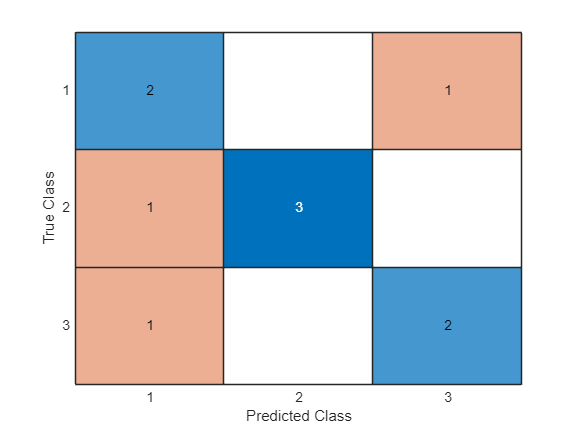

confMatrix =   ConfusionMatrixChart with properties:

    NormalizedValues: [3x3 double]
         ClassLabels: [3x1 categorical]

  Show all properties


% Creates a confusion matrix chart from true labels "actual" and predicted labels "predictions"
confMatrix = confusionchart(actual, predictions)

Components of a confusion matrix

- Each row represents the instances in an actual class

- Each column represents the instances in a predicted class

- Diagonal elements represent the number of correct predictions for each class 

- Off-diagonal elements represent the number of incorrect predictions

Metrics from the Confusion matrix

- True Positives (TP): the diagonal elements, representing correctly predicted instances for each class

- False Positives (FP): The sum of each column excluding the diagonal element

- False Negatives (FN): The sum of each row excluding the diagonal element

- True Negatives (TN): All the other elements that are not part of the row or column of the current class

**Accuracy**

- What it means: Accuracy tells us how often the model is correct. It's asking, "Out of all the predictions the model made, how many times did it get the correct answer?"

- example: if your model makes 100 predictions and gets 90 of them right, the accuracy is 90%

- Accuracy can be calculated by dividing the number of correct predictions (true positives) by the total number of predictions. 

- Normalized values from the confusion matrix are used to calculate accuracy, precision, and other metrics


$$\textrm{Accuracy}=\frac{\textrm{Total}\;\textrm{Number}\;\textrm{of}\;\textrm{Correct}\;\textrm{Predictions}}{\textrm{Total}\;\textrm{Number}\;\textrm{of}\;\textrm{Predictions}}$$


% Calculates the overall accuracy of a classification model using values from the normalized confusion matrix. 

% sum(diag(confMatrix.NormalizedValues)) represents the true positive rates for each class

% sum(confMatrix.NormalizedValues(:)) represents the total number of predictions

accuracy = sum(diag(confMatrix.NormalizedValues))/sum(confMatrix.NormalizedValues(:))

accuracy = 0.7000

**Precision**

- Precision tells us how many of the predicted positive results were actually correct. It's like asking, "Of all the emails the model said were spam, how many really were spam?" 

**Recall**

- Recall tells us how many of the actual positive results were correctly identified by the model. It's like asking, "Of all the spam emails, how many did the model catch?"

- If there were 60 spam emails in total and the model correctly identified 50 of them, the recall is 50/60 ≈ 83%

- Recall is crucial when you want to catch as many positive instances as possible, even if it means getting some false positives.

- High recall means that the model is good at finding all the positives, even if it sometimes gets it wrong.

**F1-Score**

-  The F1-score is a balance between precision and recall. It gives us a single number that represents the model's accuracy in catching positive results while avoiding false positives.

-  Think of it like an overall score for the model’s performance in terms of finding spam emails accurately and avoiding false alarms.

Now let's put precision, recall, and f1-score together in one example of code. First let's makes variables to store these metrics. 

% Gets unique class labels from the variable predictions
classes = categories(predictions); 

% Number of classes
numClasses = numel(classes);   

% Initializes an empty array to store precision
precision = zeros(numClasses, 1);

% Initializes an empty array to store recall value
recall = zeros(numClasses, 1);

% Initializes an empty array to store F1-scores
f1score = zeros(numClasses, 1);

Using the for loop below we can step through the confusion matrix to extract the values necessary to calculate the precision, recall, and F1-score. 

The equations below are used in the code to calculate precision, recall, and F1-score. These equations use true positive (TP), false positive (FP), and false negatives (FN) values extracted from the confusion matrix. 

- 
$$\textrm{Precision}=\frac{\textrm{TP}}{\textrm{TP}+\textrm{FP}}$$


- 
$$\textrm{Recall}=\frac{\textrm{TP}}{\textrm{TP}+\textrm{FN}}$$


- 
$$\textrm{Precision}=\frac{2*\left(\textrm{Precision}*\textrm{Recall}\right)}{\textrm{Precision}+\textrm{Recall}}$$


% A for loop to iterate through the confusion matrix and calculate metrics for each class
for ii = 1:numClasses
    % Gets the current class label
    class = classes{ii};
    TP = confMatrix.NormalizedValues(ii, ii); % True positives
    FP = sum(confMatrix.NormalizedValues(:, ii)) - TP; % False positives
    FN = sum(confMatrix.NormalizedValues(ii, :)) - TP; % False negatives
    precision(ii) = TP / (TP + FP); % Calculates precision
    recall(ii) = TP / (TP + FN); % Calculates recall
    f1score(ii) = 2 * (precision(ii) * recall(ii)) / (precision(ii) ...
        + recall(ii)); % Calculates F1-score

    % Displays metrics for each class
    fprintf('Class %s: Precision: %.2f%%, Recall: %.2f%%, F1-Score: %.2f%%\n', ...
        class, (precision(ii) * 100), (recall(ii) * 100), (f1score(ii) * 100))
end

Class 1: Precision: 50.00%, Recall: 66.67%, F1-Score: 57.14%
Class 2: Precision: 100.00%, Recall: 75.00%, F1-Score: 85.71%
Class 3: Precision: 66.67%, Recall: 66.67%, F1-Score: 66.67%


Below we calculate the total number of true positives, false positives, and false negatives. These metrics are essential for evaluating the performance of the classification model. 

% Calculates the total true positive instances across all classes
TP_total = sum(diag(confMatrix.NormalizedValues))

TP_total = 7

% Calculates the total false positive count across all classes
FP_total = sum(confMatrix.NormalizedValues, 1) - diag(confMatrix.NormalizedValues)'

FP_total =      2     0     1


% Calculates the total false negative across all classes
FN_total = sum(confMatrix.NormalizedValues, 2) - diag(confMatrix.NormalizedValues)

FN_total =      1
     1
     1


## Evaluating Regression Models

For regression tasks, evaluating the model's performance involves using different metrics compared to classification tasks. The most common metrics used for regression model evaluation are Mean Absolute Error (MAE), Mean Squared Error (MSE), and R-squared (R²). Let's create more example prediction and actual values.

% Example actual and predicted values
actual = [3, -0.5, 2, 7];
predictions = [2.5, 0.0, 2, 8];

% Convert to column vectors
actual = actual(:);
predictions = predictions(:);
 

**Mean Absolute Error (MAE)**

- MAE is the average of the absolute differences between the predicted values and the actual values.

- It provides a measure of how close the predictions are to the actual outcomes.

% Calculates MAE using the variables actual and predictions
MAE = mean(abs(actual - predictions))

MAE = 0.5000

The interpretation of a "good" or "bad" MAE depends on the context of the problem and the scale of the data.

Examples of varying contexts: 

- For predicting house prices, an MAE of $10,000 might be acceptable given the high value of the houses. 

- However, in predicting the temperature, an MAE of 10 degrees might be considered very poor.

Examples of varying scales: 

- If you're predicting values that typically range from 1 to 100, an MAE of 1 might be quite good. 

- If the values range from 1,000 to 10,000, an MAE of 1 might be excellent.

**Mean Squared Error (MSE)**

- MSE is the average of the squared differences between the predicted values and the actual values.

- It emphasizes larger errors more than MAE because errors are squared.

% Calculates MSE
MSE = mean((actual - predictions).^2)

MSE = 0.3750

Interpreting whether an MSE is "good" or "bad" depends on the context of the problem, similar to MAE, but with additional emphasis on larger errors due to the squaring:

Context and Domain:

- In domains where precision is crucial, a smaller MSE is desired.

- The impact of the squared error means that larger errors are penalized more heavily, making MSE sensitive to outliers.

Scale of the Data:

- The absolute values of the data significantly impact the interpretation of MSE.

- For data with a large range, MSE tends to be larger, while for data with a smaller range, it should be smaller.

**Example with both MAE and MSE**

Predicting House Prices

- Suppose the actual house prices range from $100,000 to $500,000.

- An MAE of $5,000 might be considered quite good because it represents a small percentage of the total price range (around 1-5%)

- An MSE of $250,000,000 (e.g., if the errors are around $500 each squared) might be considered good in this context because it indicates relatively small average errors

Predicting Daily temperature

- Suppose the actual temperatures range from 0 to 40 degrees Celsius.

- An MAE of 2 degrees might be acceptable, while an MAE of 10 degrees would be considered poor since it indicates significant deviations from the actual values.

- An MSE of 25 (e.g., if the errors are around 5 degrees each squared) would be considered poor, indicating significant deviations from the actual values.

**R-squared (R²)**

- R², also known as the coefficient of determination, indicates how well the regression predictions approximate the real data points.

- An R² of 1 indicates that the regression predictions perfectly fit the data.

% Calculates total sum of squares- total variance in actual values
SST = sum((actual - mean(actual)).^2);

% Calculates residual sum of squares- variance in residuals (errors)
% between actual and predicted values
SSE = sum((actual - predictions).^2);

% Calculates R-squared 
R2 = 1 - (SSE / SST)

R2 = 0.9486

**Interpretation of R-squared values**

- R² has a range of 0 to 1. While an R² of 1 indicates a perfect fit, an R² of 0 indicated a very poor fit. Furthermore, when deciding if the R² is acceptable, it depends on the context:

- High R²: Generally indicates a model that fits the data well. However, an excessively high R² (close to 1) could also indicate overfitting, especially if the model has a large number of predictors.

- Low R²: Indicates that the model does not explain much of the variance in the dependent variable. However, what constitutes a "low" R² can depend on the context and the field of study. For instance, in social sciences an an R² value around 0.3 might be considered acceptable while in physical sciences, an R² value below 0.9 might be considered poor.

## Continuing the FIFA 23 Example

Let’s use the code from Section 7 so we can continue our FIFA example. In the code block below, we will quickly go through the steps introduced in Section 7 and introduce two new steps. Steps 1, 3, and 5 do not require coding, so they do not appear in the code below. 

**Step 2: Import data**

clear; clc;
% Import data
fifa23 = readtable("/MATLAB Drive/MATLAB - Section 08 (Both - File Share)/Data/FIFA 23 male players.csv");
 

**Step 4: Split Data Into Training & Testing Sets**

% Clean the data by removing missing data from the variables (shooting, passing, dribbling, defending)
clean_fifa23 = rmmissing(fifa23, 'DataVariables',{'shooting', 'passing', 'dribbling', 'defending'});

% Create a cvpartition in order to define training and test sets for validating the model using cross-validation
cv = cvpartition(height(clean_fifa23), 'HoldOut', 0.2);

% Put data from cvpartition into variables
trainData = clean_fifa23(training(cv),:);
testData = clean_fifa23(test(cv),:);


**Step 6: Fitting a Model to Your Data**

% Trains the model
mdl = fitlm(trainData,'overall ~ shooting + passing + dribbling + defending')

mdl = Linear regression model:
    overall ~ 1 + shooting + passing + dribbling + defending

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      26.215     0.096002    273.07             0
    shooting        0.21931    0.0016587    132.21             0
    passing        0.013286     0.002607    5.0964    3.4674e-07
    dribbling       0.24375    0.0026027    93.654             0
    defending       0.24111    0.0010644    226.53             0


Number of observations: 114892, Error degrees of freedom: 114887
Root Mean Squared Error: 4.2
R-squared: 0.634,  Adjusted R-Squared: 0.634
F-statistic vs. constant model: 4.97e+04, p-value = 0

**Step 7: Run Model Using Your Test Dataset**

Now, let's create our response and predictor variables from the testData made using the cvpartition function. Recall that cvpartition sets aside a portion of the overall dataset to use for testing later on. Because we already know what the response variables are, this is an example of a supervised machine learning model.

% Predictor variables
testPred = testData(:,{'shooting','passing', 'dribbling', 'defending'});

% Response variable: this will act as the Actual data
testRes = testData.overall;
disp(testRes)

    87
    87
    86
    86
    85
    85
    84
    84
    83
    83
    83
    83
    83
    83
    83
    83
    83
    83
    82
    82
    82
    82
    82
    82
    81
    81
    81
    81
    81
    81
    81
    81
    80
    80
    80
    80
    80
    80
    80
    80
    80
    80
    80
    80
    80
    80
    80
    79
    79
    79
    79
    79
    79
    79
    79
    79
    79
    79
    79
    79
    79
    79
    79
    79
    79
    79
    79
    79
    79
    78
    78
    78
    78
    78
    78
    78
    78
    78
    78
    78
    78
    78
    78
    78
    78
    78
    78
    77
    77
    77
    77
    77
    77
    77
    77
    77
    77
    77
    77
    77
    77
    77
    77
    77
    77
    77
    77
    77
    77
    77
    76
    76
    76
    76
    76
    76
    76
    76
    76
    76
    76
    76
    76
    76
    76
    76
    76
    76
    76
    76
    76
    76
    76
    76
    76
    76
    76
    76
    76
    76
    76
    76
    76

Ok, now that we've fit the model to the data and made our testing data, it's time to make predictions using the predict function.

assign the predictions to a variable

- The predict function uses two inputs: the first is the model you trained

- The second input is the predictor variables

- The output will be the predicted response variables

% Performs predictions using the trained model on the test dataset
pred = predict(mdl,testPred)

pred =    80.8205
   81.1856
   74.2999
   76.3177
   74.7334
   74.1556
   72.7574
   72.9264
   77.1566
   73.5610


**Step 8: Evaluate the Model**

Evaluate the model using the metrics introduced earlier in this section. 

% Calculates mean absolute error
mae = mean(abs(pred - testRes))

mae = 3.3896

% Calculates mean squared error
mse = mean((pred - testRes).^2)

mse = 17.7152

% Calculates R-squared
SST = sum((testRes - mean(testRes)).^2); % Total sum of squares
SSE = sum((pred - testRes).^2); % Sum of Squared errors
R2 = 1 - SSE/SST

R2 = 0.6325

## Refining your model

After evaluating your model, you may have some undesirable metrics. You might have a low accuracy, an R-squared of 1, etc. There is no one way to fix issues like those, so the best way to start would be by reexamining your data and the model used. The model you may have picked might not be the best fit for your data. Use the documents and lessons provided to you as a resource and remember that every project will be specific to you.

## **MATLAB Documentation **

Some of the functions in the above code may seem unfamiliar or you may want to jog your memory on them. Recall the help function demonstrated in lesson 7. Here are also some links to MATLAB documentation if you want to learn more.

- categorical: [https://www.mathworks.com/help/matlab/ref/categorical.html](https://www.mathworks.com/help/matlab/ref/categorical.html) 

- sum: [https://www.mathworks.com/help/matlab/ref/sum.html](https://www.mathworks.com/help/matlab/ref/sum.html) 

- diag: [https://www.mathworks.com/help/matlab/ref/diag.html](https://www.mathworks.com/help/matlab/ref/diag.html) 

- numel: [https://www.mathworks.com/help/matlab/ref/double.numel.html](https://www.mathworks.com/help/matlab/ref/double.numel.html) 

- zeros: [https://www.mathworks.com/help/matlab/ref/zeros.html](https://www.mathworks.com/help/matlab/ref/zeros.html) 

- if-else statements (conditionals): [https://www.mathworks.com/help/matlab/ref/if.html](https://www.mathworks.com/help/matlab/ref/if.html) 

- for loops: [https://www.mathworks.com/help/matlab/ref/for.html](https://www.mathworks.com/help/matlab/ref/for.html) 

- abs: [https://www.mathworks.com/help/matlab/ref/abs.html](https://www.mathworks.com/help/matlab/ref/abs.html) 

- mean: [https://www.mathworks.com/help/matlab/ref/mean.html](https://www.mathworks.com/help/matlab/ref/mean.html) 

- any: [https://www.mathworks.com/help/symbolic/any.html](https://www.mathworks.com/help/symbolic/any.html) 

- isnan: [https://www.mathworks.com/help/matlab/ref/isnan.html](https://www.mathworks.com/help/matlab/ref/isnan.html) 

- isinf: [https://www.mathworks.com/help/matlab/ref/isinf.html](https://www.mathworks.com/help/matlab/ref/isinf.html) 

- MATLAB operators and special characters: [https://www.mathworks.com/help/matlab/matlab_prog/matlab-operators-and-special-characters.html](https://www.mathworks.com/help/matlab/matlab_prog/matlab-operators-and-special-characters.html) 